run('DataGeneration.mlx')

# Data Preparation

clc
clear all
close all
rng(0)

Topology = 'M2C';

A = [1  1  1  0  0  0;
     0  0  0  1  1  1;
    -1  0  0 -1  0  0;
     0 -1  0  0 -1  0;
     0  0 -1  0  0 -1];
pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
n     = size(N, 2);
pinvN = pinv(N);

# Load data from random data generator

buffer_name       = 'train100k';
buffer_train      = load(strcat(['ImitationLearningSimulink\TrainingData\Data\', buffer_name, '.mat']), 'buffer').buffer;
buffer_validation = load('ImitationLearningSimulink\TrainingData\Data\validation.mat', 'buffer').buffer;

buffer_train

buffer_train = struct with fields:
    X: [14×10000 double]
    Y: [3×10000 double]

buffer_validation

buffer_validation = struct with fields:
    X: [14×1000 double]
    Y: [3×1000 double]


buffer   = struct();
buffer.X = [buffer_train.X, buffer_validation.X];
buffer.Y = [buffer_train.Y, buffer_validation.Y];

X = buffer.X;
Y = buffer.Y;

Nsamples = size(X, 2)

Nsamples = 11000

Ninputs  = size(X, 1)

Ninputs = 14

Noutputs = size(Y, 1)

Noutputs = 3

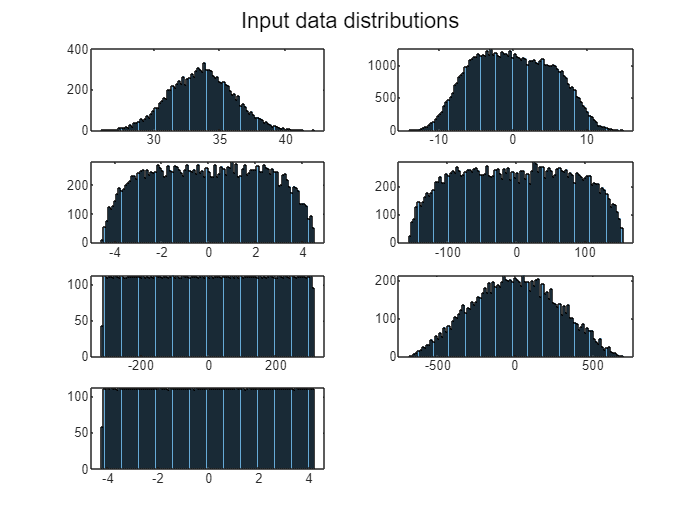


figure
subplot(4, 2, 1)
histogram(X(1, :), 100)       % mean(Ec)
subplot(4, 2, 2)
histogram(X(2:1+m, :), 100)   % Ec-mean(Ec)
subplot(4, 2, 3)
histogram(X(2+m:3+m, :), 100) % im_ab
subplot(4, 2, 4)
histogram(X(4+m:5+m, :), 100) % vm_ab
subplot(4, 2, 5)
histogram(X(6+m, :), 100)     % wy
subplot(4, 2, 6)
histogram(X(7+m, :), 100)     % pm
subplot(4, 2, 7)
histogram(X(8+m, :), 100)     % iP
sgtitle('Input data distributions')

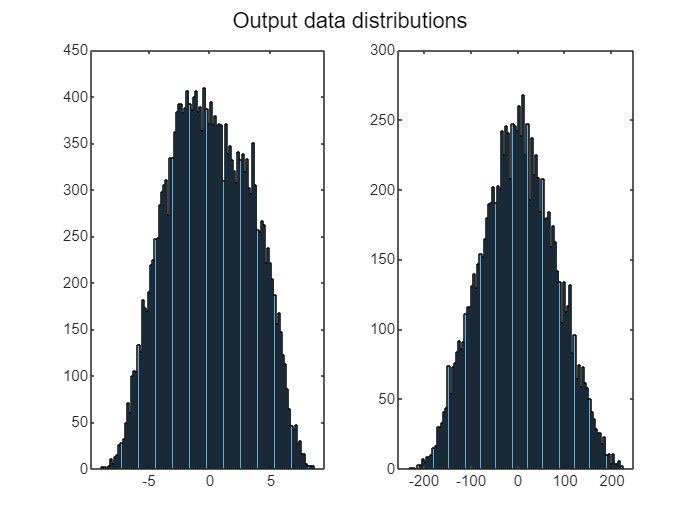


figure
subplot(1, 2, 1)
histogram(Y(1:n, :), 100)
subplot(1, 2, 2)
histogram(Y(end, :), 100)
sgtitle('Output data distributions')

Absolute maximum L.I. circulating and basic currents (assuming ie_ref_max~ie_max)

T = reference_frame_transforms;
Tabc2ab = T.abc2ab; % Three-phase to alpha-beta
Tab2abc = T.ab2abc; % Alpha-beta to three-phase

im = Tab2abc * X(2+m:3+m, :);
iP = X(8+m, :);
ixy = [iP; -iP; im];

iB = pinvA * ixy;
max(abs(iB(:)))

ans = 3.6145


ie = Y(1:n, :);
ie_max = max(abs(ie(:)))

ie_max = 8.8869

## Induction Machine (IM)

IM = struct();

Nominal values and structural parameters

IM.VLLN = 380;
IM.fN   = 50;
IM.PN   = 3000;
IM.FPn  = 0.81;
IM.SN   = IM.PN / IM.FPn;
IM.wN   = 1450 * pi / 30;
IM.IN   = IM.SN / (IM.VLLN * sqrt(3));
IM.TN   = IM.PN / IM.wN;
IM.FrN  = sqrt(2/3) * IM.VLLN / (2 * pi * IM.fN);
IM.np   = 2;

Lumped parameters

IM.J    = 0.006;
IM.Rs   = 1.8;
IM.Rr   = 1.8;
IM.Los  = 2.6e-3;
IM.Lor  = 2.6e-3;
IM.Lm   = 235.1e-3;
IM.Ls   = IM.Los + IM.Lm;
IM.Lr   = IM.Lor + IM.Lm;

IM.kr    = IM.Lm / IM.Lr;
IM.ks    = IM.Lm / IM.Ls;
IM.tau_r = IM.Lr / IM.Rr;
IM.o     = 1 - IM.ks * IM.kr;
IM.Ro    = IM.Rs + IM.Rr * IM.kr^2;
IM.Lo    = IM.o * IM.Ls;
IM.tau_o = IM.Lo / IM.Ro;
IM.kT    = 1.5 * IM.np * IM.kr;

IM.isdN  = IM.FrN / IM.Lm;

## Modular Multilevel Converter (M2C)

M2C = struct(); % Modular Multilevel Converter parameters

Parameters

M2C.ax       = [1, 1, 1, 0, 0, 0;       % Input incidence matrix
                0, 0, 0, 1, 1, 1];
M2C.ay       = [1, 0, 0, 1, 0, 0;       % Output incidence matrix
                0, 1, 0, 0, 1, 0;
                0, 0, 1, 0, 0, 1];
M2C.Mx       = M2C.ax' * M2C.ax;
M2C.My       = M2C.ay' * M2C.ay;
M2C.p        = size(M2C.ax, 1);         % # of input ports
M2C.q        = size(M2C.ay, 1);         % # of output ports
M2C.A        = [M2C.ax;                 % Incidence matrix
               -M2C.ay];
M2C.m        = size(M2C.A, 2);          % # of clusters
M2C.pinvA    = pinv(M2C.A);             % Incidence matrix inverse
M2C.N        = null(M2C.A, 'rational'); % Nullspace matrix
M2C.n        = size(M2C.N, 2);          % # of LICCs
M2C.pinvN    = pinv(M2C.N);             % Nullspace matrix inverse
M2C.Rb       = 0.2;                        % Branch resistance
M2C.Lb       = 5e-3;                       % Branch inductance
M2C.Csm      = 987e-6;                     % Submodule capacitance
M2C.Nsm      = 4;                          % Number of submodules per cluster
M2C.C        = M2C.Csm / M2C.Nsm;          % Equivalent branch capacitance
M2C.As       = -eye(M2C.m)*M2C.Rb/M2C.Lb;  % Continuous state matrix
M2C.Bs       = -eye(M2C.m)/M2C.Lb;         % Continuous input matrix
M2C.invBs    = inv(M2C.Bs);                % Input matrix inverse
M2C.Vdc      = 520;                        % DC-link voltage
M2C.Ax_max   = M2C.Vdc / 2;                % Max. input voltage
M2C.Ay_max   = IM.VLLN * sqrt(2/3) * 25/IM.fN; % Max. output voltage (half manchine's nominal)
M2C.ix_max   = 4.2;                        % Max. input current
M2C.iy_max   = 4.5;                        % Max. output current
M2C.is_max   = 8.5;                        % Max. branch current
M2C.Vc_m_ref = 520;                        % Mean cluster capacitor voltage reference
M2C.Ec_m_ref = M2C.C / 2 * M2C.Vc_m_ref^2; % Mean cluster energy reference

Input/outputs limits

Ax0 = M2C.Ax_max;
Ay0 = M2C.Ay_max;
VCdiff = 0.15;
m = M2C.m;
n = M2C.n;
C = M2C.C;
ix_max = M2C.ix_max;
iy_max = M2C.iy_max;
is_max = M2C.is_max;
vo_max = M2C.Vdc/2;

Emean = C/2 * M2C.Vc_m_ref^2;                   % mean(Ec)
Ediff = Emean * ((1+VCdiff)^2 - 1) *ones(m, 1); % Ec-mean(Ec)
IY    = iy_max                     *ones(2, 1); % iya, iyb
VY    = Ay0                        *ones(2, 1); % vyac, vybc
PY    = iy_max * Ay0;                           % py1, py2
WY    = 100*pi;                                 % wy
IX    = ix_max;                                 % ix
Xmax = [Emean; Ediff; IY; VY; WY; PY; IX]

Xmax =    33.3606
   10.7588
   10.7588
   10.7588
   10.7588
   10.7588
   10.7588
    4.5000
    4.5000
  155.1344



IE = is_max *ones(n, 1); % LICCs
VO = vo_max;             % CMV

Ymax = [IE; VO]

Ymax =     8.5000
    8.5000
  260.0000


# Preprocessing

Input/output sizes

size(X)

ans =           14       11000


size(Y)

ans =            3       11000


Normalization

X = X ./ Xmax;
X(1, :) = X(1, :) - 1;
X(1, :) = X(1, :) / VCdiff;
Y = Y ./ Ymax;
% Y = clip(Y, -1, 1);

Training/validation split

X_tr  = buffer_train.X ./ Xmax;
X_tr(1, :) = X_tr(1, :) - 1;
Y_tr  = buffer_train.Y ./ Ymax;
X_val = buffer_validation.X ./ Xmax;
X_val(1, :) = X_val(1, :) - 1;
Y_val = buffer_validation.Y ./ Ymax;

Data augmentation with white noise

% X_tr = [X_tr, X_tr+0.01*randn(size(X_tr))]
% Y_tr = [Y_tr, Y_tr]

Transform to dlarray

dlX     = dlarray(X, 'CB');
dlY     = dlarray(Y, 'CB');
dlX_tr  = dlarray(X_tr, 'CB');
dlY_tr  = dlarray(Y_tr, 'CB');
dlX_val = dlarray(X_val, 'CB');
dlY_val = dlarray(Y_val, 'CB');
dsX_tr  = arrayDatastore(dlX_tr, 'IterationDimension', 2);
dsY_tr  = arrayDatastore(dlY_tr, 'IterationDimension', 2);
dsXY_tr = combine(dsX_tr, dsY_tr);

# Exploratory data analysis

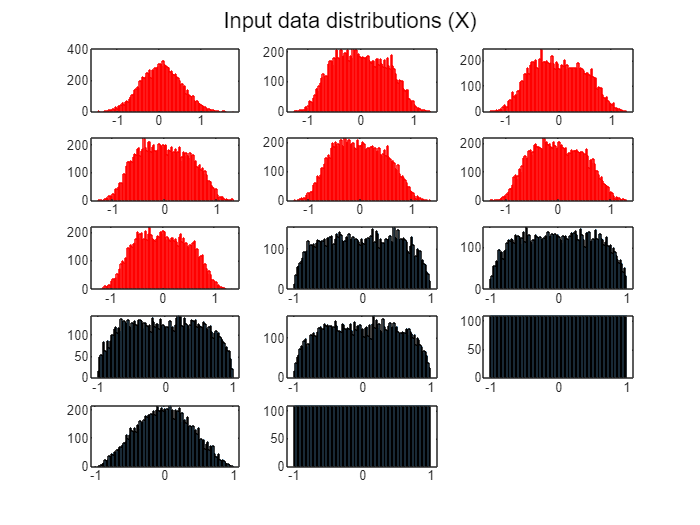

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if max(abs(X(idx, :))) > 1
        histogram(X(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100);
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

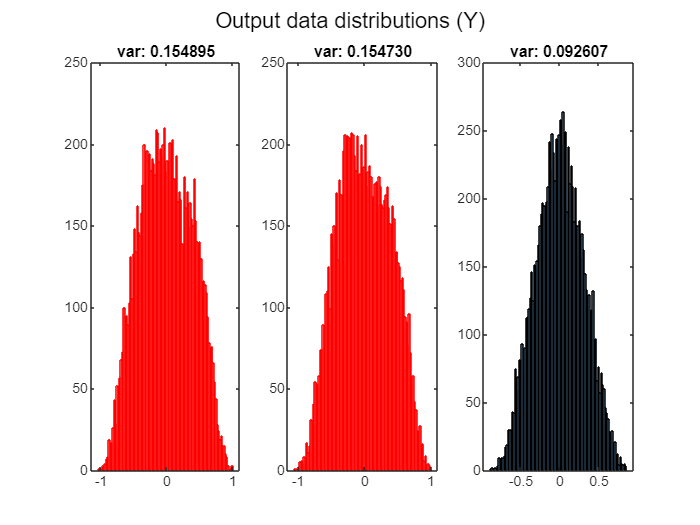


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if max(abs(Y(idx, :))) > 1
        histogram(Y(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100)
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;